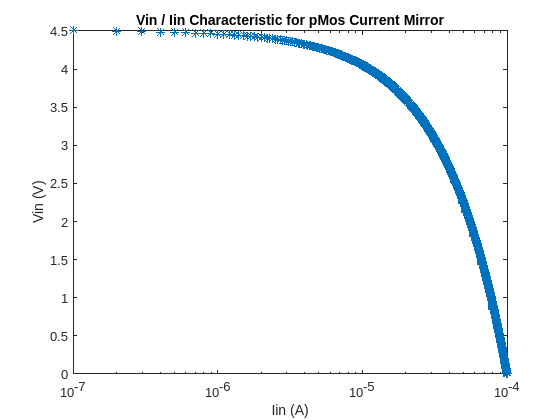

loadspice("Draft1.txt");
Vout = linspace(0,4.5,1001);
semilogx(Iin,flip(Vout),'*');
xlabel("Iin (A)")
ylabel("Vin (V)")
title("Vin / Iin Characteristic for pMos Current Mirror")

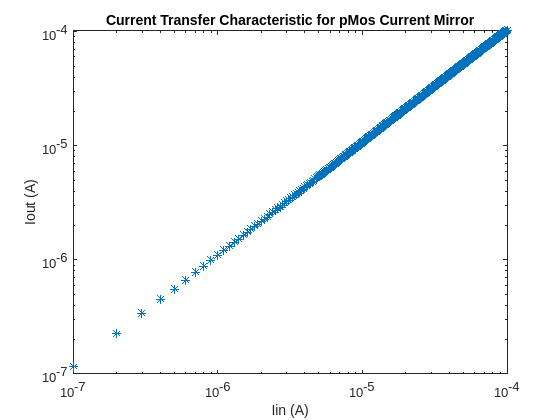

loglog(Iin,Iout, "*")
xlabel("Iin (A)")
ylabel("Iout (A)")
title("Current Transfer Characteristic for pMos Current Mirror")

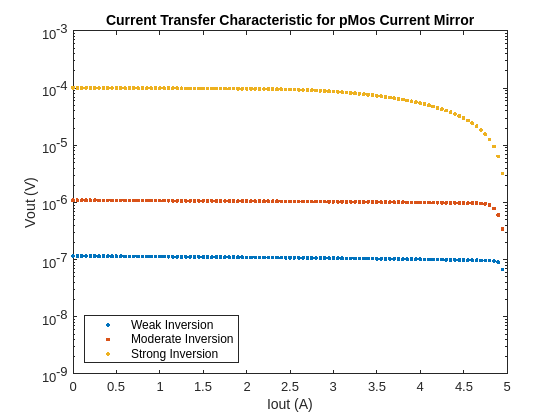

loadspice("exp3_weak.txt");
loadspice("exp3_mod.txt");
loadspice("exp3_strong.txt");


Vout_exp3 = linspace(0,5,101);
semilogy(Vout_exp3,Iout_weak,'.');
hold on;
semilogy(Vout_exp3,Iout_mod,'.');
hold on;
semilogy(Vout_exp3,Iout_strong,'.')
xlabel("Iout (A)")
ylabel("Vout (V)")
legend("Weak Inversion","Moderate Inversion", "Strong Inversion", 'Location',"southwest")
ylim([10e-10 10e-4])
title("Current Transfer Characteristic for pMos Current Mirror")

We can see that the overall behaviour is the same but the simulated experiment is using ideal components.